# Pregunta 3

## Maximiliano Rivera

Los códigos utilizados están en la siguiente plataforma:

[https://github.com/Marivera3/Algebra-Lineal-Numerica](https://github.com/Marivera3/Algebra-Lineal-Numerica)

Esto fueron implementados por mi, basado en los apuntes del libro texto guía L.N.Trefetehn.

## Problema 3.1

La matriz a considerar es la siguiente

A = [1 2 3; 4 5 6; 7 8 7; 4 2 3; 4 2 2];
cond(A)

ans = 12.4508

[Q, R] = qr(A);

Para calcular el error se utiliza la norma 2. El error asociado a esta descomposición es:

e = norm(Q*R - A)

e = 2.8383e-15

rii = diag(R);

Luego, calculamos su descomposición $QR$ con los siguiente algoritmos implementados:

- Factorización QR por método de Gram-Schmidt clásico.

[Q1, R1] = QRbyGSC(A);

El error asociado es:

e1 = norm(Q1*R1 - A)

e1 = 1.1802e-15

rii1 = diag(R1);

- Factorización QR por método de Gram-Schmidt modificado.

[Q2, R2] = QRbyGSM(A);

El error asociado es:

e2 = norm(Q2*R2 - A)

e2 = 1.1935e-15

rii2 = diag(R2);

- Factorización QR por método de Householder.

[Q3, R3] = QRbyHouseholder(A);

El error asociado es:

e3 = norm(Q3*R3 - A)

e3 = 2.8450e-15

rii3 = diag(R3);

El gráfico de las componentes diagonales de la matriz triagular superior es el siguiente:

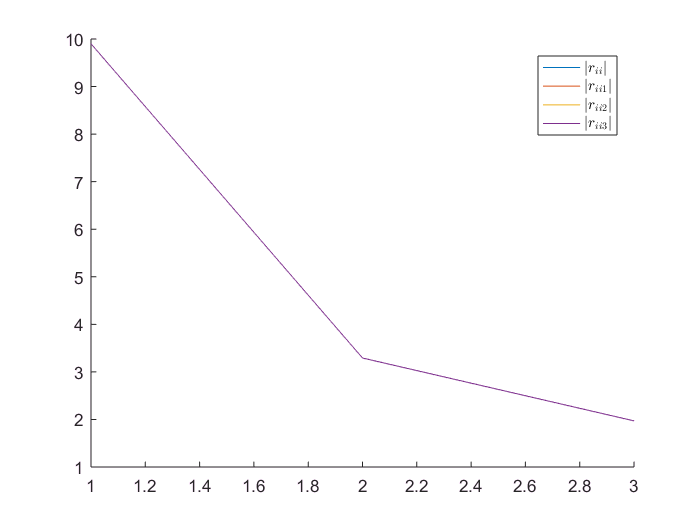

fig = figure();
ax = axes(fig); 
set(ax,'nextplot','add'); 
o = plot(ax, abs(rii));
o1 = plot(ax, abs(rii1));
o2 = plot(ax, abs(rii2));
o3 = plot(ax, abs(rii3));
leg = legend([o,o1, o2, o3],'$|r_{ii}|$','$|r_{ii1}|$', '$|r_{ii2}|$', '$|r_{ii3}|$');
set(leg,'interpreter','latex'); 

Donde los valores de $r_{iiN}$, con $N = {0, 1, 2, 3}$representan la diagonal de la matriz R respectiva. Del gráfico se concluye que estos valores son idénticos a excepto de un signo, esto se debe a que es posible multiplicar por un $-1$ en ambas matrices, por lo que, como también los errores relativos son pequeños, los métodos utilizados son equivalentes. Notemos que, por sobre todo esto, la matriz está bien condicionada.

## Pregunta 3.2

Ahora se utiliza una matriz de Hilbert con $n = 20
$. Esta matriz es conocida por ser mal condicionada.

H = hilb(20);
cond(H)

ans = 2.1065e+18

[Q, R] = qr(H);

Para calcular el error se utiliza la norma 2. El error asociado a esta descomposición es:

e = norm(Q*R - H)

e = 3.5079e-16

rii = diag(R);

Luego, calculamos su descomposición $QR$ con los siguiente algoritmos implementados:

- Factorización QR por método de Gram-Schmidt clásico.

[Q1, R1] = QRbyGSC(H);

El error asociado es:

e1 = norm(Q1*R1 - H)

e1 = 3.2164e-17

rii1 = diag(R1);

- Factorización QR por método de Gram-Schmidt modificado.

[Q2, R2] = QRbyGSM(H);

El error asociado es:

e2 = norm(Q2*R2 - H)

e2 = 6.6324e-17

rii2 = diag(R2);

- Factorización QR por método de Householder.

[Q3, R3] = QRbyHouseholder(A);

El error asociado es:

e3 = norm(Q3*R3 - A)

e3 = 2.8450e-15

rii3 = diag(R3);

El gráfico de las componentes diagonales de la matriz triagular superior es el siguiente:

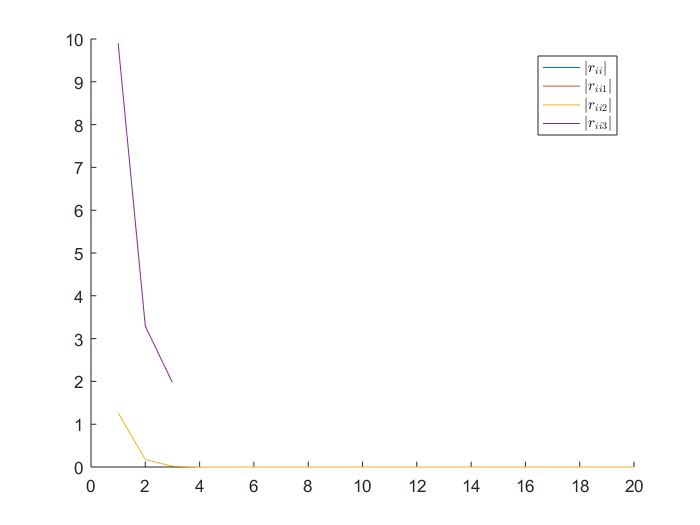

fig = figure();
ax = axes(fig); 
set(ax,'nextplot','add'); 
o = plot(ax, abs(rii));
o1 = plot(ax, abs(rii1));
o2 = plot(ax, abs(rii2));
o3 = plot(ax, abs(rii3));
leg = legend([o,o1, o2, o3],'$|r_{ii}|$','$|r_{ii1}|$', '$|r_{ii2}|$', '$|r_{ii3}|$');
set(leg,'interpreter','latex'); 

Del gráfico se puede ver que los coeficientes de R obtenido por Householder difiere del resto. Se grafican los demas $r_{ii}$

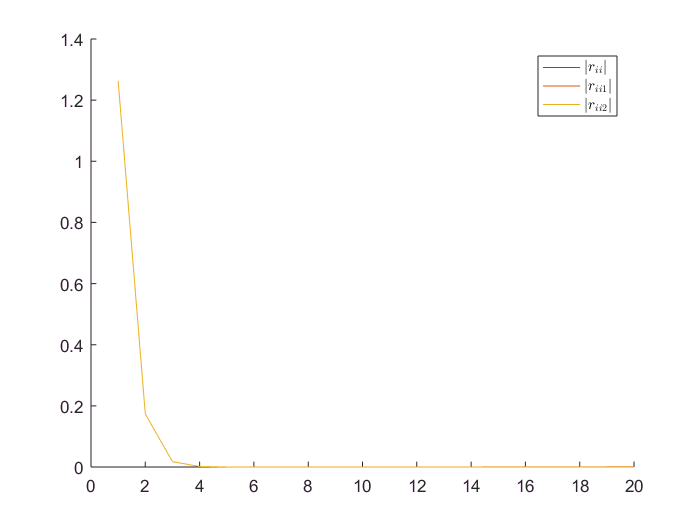

fig2 = figure();
ax2 = axes(fig2); 
set(ax2,'nextplot','add'); 
o = plot(ax2, abs(rii));
o1 = plot(ax2, abs(rii1));
o2 = plot(ax2, abs(rii2));
leg = legend([o,o1, o2],'$|r_{ii}|$','$|r_{ii1}|$', '$|r_{ii2}|$');
set(leg,'interpreter','latex'); 

De este gráfico, podemos notar que el método de Gram-Schmidt es más estable que el método dado por Householder. Esto es facil de notar cuando se utiliza una matriz mal condicionada.